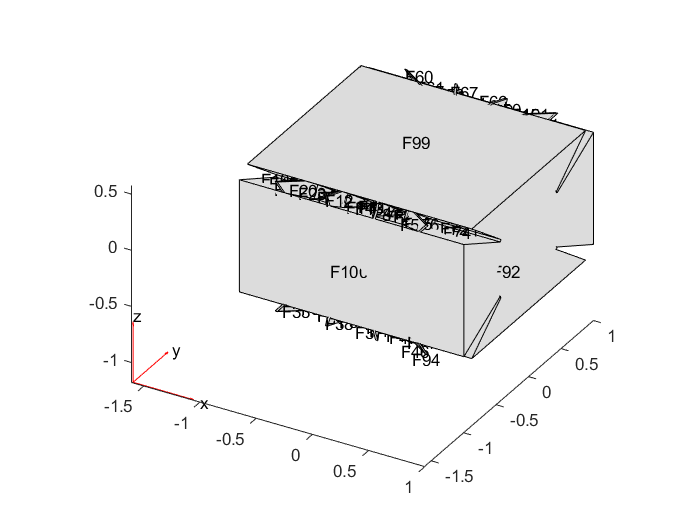

stlname = "cut100_2020";
model = createpde();
importGeometry(model,stlname+".STL");
pdegplot(model,'FaceLabels','on')

g=model.Geometry;
tol = 1e-4;

## Find the coordinates of all the vertices

vertices = zeros(g.NumVertices,3);
for i = 1:g.NumVertices
    vertices(i,:) = g.vertexCoordinates(i);
end

## Find the associativities between faces and vertices

f2v = cell(g.NumFaces,1);
v2f = cell(g.NumVertices,1);
f2v(:) = {[]};
v2f(:) = {[]};
for i = 1:g.NumFaces
    f2v{i} = g.findVertices('region','Face',i);
    for j = 1:length(f2v{i})
        v2f{f2v{i}(j)} = [v2f{f2v{i}(j)};i];
    end
end

## Find the face number of the 6 faces of the overall cuboid

cuboid = [max(vertices);min(vertices)];
cuboidf = [];
for i = 1:g.NumFaces
    cuboidv = vertices(f2v{i},:);
    if all(eqtol(cuboidv(:,1),cuboid(2,1),tol)) || all(eqtol(cuboidv(:,1),cuboid(1,1),tol)) || ...
            all(eqtol(cuboidv(:,2),cuboid(2,2),tol)) || all(eqtol(cuboidv(:,2),cuboid(1,2),tol)) || ...
            all(eqtol(cuboidv(:,3),cuboid(2,3),tol)) || all(eqtol(cuboidv(:,3),cuboid(1,3),tol))
        cuboidf = [cuboidf,i];
    end
end

## Find vertices which belong to one blade

% Find Vertex on the edge x = min, y = min. Note that the orientation of the trap affect
% the following codes.
blade1z = -100;
for i = 1:g.NumVertices
    coord = vertices(i,:);
    if eqtol(coord(1),cuboid(1,1),tol) && eqtol(coord(2),cuboid(1,2),tol) && coord(3)<cuboid(1,3)-tol
        if coord(3)>blade1z
           blade1z  = coord(3);
        end
    end
end
% Find start points in all target electrodes
% (x = 0, z = z0)
blade1v = find(eqtol(vertices(:,2),cuboid(1,1),tol)&eqtol(vertices(:,3),blade1z,tol));
blade1vx = vertices(blade1v,1);
[~,index] = sort(blade1vx);
blade1v = blade1v(index);

## Find the faces of each electrode

% Aside for the 6 faces of the cuboid, the faces of one electrode are connected
% and only connected to faces of the same electrode
elef1 = cell(length(blade1v),1);
elef1(:) = {[]};
for i = 1:length(blade1v)
    elef1{i} = setdiff(v2f{blade1v(i)},cuboidf); % Substract faces of the cuboid
    newf = [];
    while true
        newv = [];
        for j = 1:length(elef1{i})
            newv = [newv;f2v{elef1{i}(j)}]; % Vertices of all the faces already found
        end
        newv = unique(newv);
        newf = [];
        for j = 1:length(newv)
            newf = [newf;v2f{newv(j)}]; % Faces contains the vertices already found
        end
        newf = setdiff(newf,cuboidf,'sorted'); % Substract faces of the cuboid
        if isequal(newf,elef1{i}) % Whether new faces are found
            break
        else
            elef1{i} = newf;
        end
    end
end
blademym = elef1(1);
j = 1;
for i = 2:length(blade1v)
    if ~isequal(elef1{i},blademym{j})
        j = j+1;
        blademym = [blademym;elef1{i}];
    end
end

## Another Blade

blade1z = 100;
for i = 1:g.NumVertices
    coord = vertices(i,:);
    if eqtol(coord(1),cuboid(2,1),tol) && eqtol(coord(2),cuboid(2,2),tol) && coord(3)<cuboid(1,3)-tol
        if coord(3)<blade1z
           blade1z  = coord(3);
        end
    end
end
% Find start points in all target electrodes
% (x = 0, z = z0)
blade1v = find(eqtol(vertices(:,2),cuboid(2,1),tol)&eqtol(vertices(:,3),blade1z,tol));
blade1vx = vertices(blade1v,1);
[~,index] = sort(blade1vx);
blade1v = blade1v(index);
elef1 = cell(length(blade1v),1);
elef1(:) = {[]};

for i = 1:length(blade1v)
    elef1{i} = setdiff(v2f{blade1v(i)},cuboidf); % Substract faces of the cuboid
    newf = [];
    while true
        newv = [];
        for j = 1:length(elef1{i})
            newv = [newv;f2v{elef1{i}(j)}]; % Vertices of all the faces already found
        end
        newv = unique(newv);
        newf = [];
        for j = 1:length(newv)
            newf = [newf;v2f{newv(j)}]; % Faces contains the vertices already found
        end
        newf = setdiff(newf,cuboidf,'sorted'); % Substract faces of the cuboid
        if isequal(newf,elef1{i}) % Whether new faces are found
            break
        else
            elef1{i} = newf;
        end
    end
end

blade0y0 = elef1(1);
j = 1;
for i = 2:length(blade1v)
    if ~isequal(elef1{i},blade0y0{j})
        j = j+1;
        blade0y0 = [blade0y0;elef1{i}];
    end
end

save(stlname+".mat","cuboid","blade0y0","blademym","-mat")

function r = eqtol(x,y,tol)
% equal function with tolerance
if  isequal(size(y) , [1,1])
    r = (y-tol<x)&(x<y+tol);
    return
end
cmp = [y-tol<x,x<y+tol];
r = all(cmp(:));
end
% % Find the vertices number of the corner of the overall cuboid
% %    8----7
% %   /|   /|
% %  / 4  / 3
% % 5----6 /   z y
% % |/   |/    |/
% % 1----2     --x
% cuboid = [2,4,2];
% corners = zeros(8,1);
% tol = 1e-8;
% for i = 1:g.NumVertices
%     coord = vertices(i,:);
%     if eqtol(coord,[0,0,0],tol)
%         corners(1) = i;
%     elseif eqtol(coord,[cuboid(1),0,0],tol)
%         corners(2) = i;
%     elseif eqtol(coord,[cuboid(1),cuboid(2),0],tol)
%         corners(3) = i;
%     elseif eqtol(coord,[0,cuboid(2),0],tol)
%         corners(4) = i;
%     elseif eqtol(coord,[0,0,cuboid(3)],tol)
%         corners(5) = i;
%     elseif eqtol(coord,[cuboid(1),0,cuboid(3)],tol)
%         corners(6) = i;
%     elseif eqtol(coord,[cuboid(1),cuboid(2),cuboid(3)],tol)
%         corners(7) = i;
%     elseif eqtol(coord,[0,cuboid(2),cuboid(3)],tol)
%         corners(8) = i;
%     end
% end
% if any(corners==0)
%     error("All corners are not found.");
% end